# **STATISTICS Lab 1**

clear; close all;

% Insert your names and NIAs here:

Name{1} = 'Adrià Coll Ortega';
NIA{1}  = 253640;
Name{2} = 'Jan Corcho Artigas';
NIA{2}  = 242320;
Name{3} = 'Jordi Alfonso Poza';
NIA{3}  = 172142;      

## Question  1

*(1 point)*

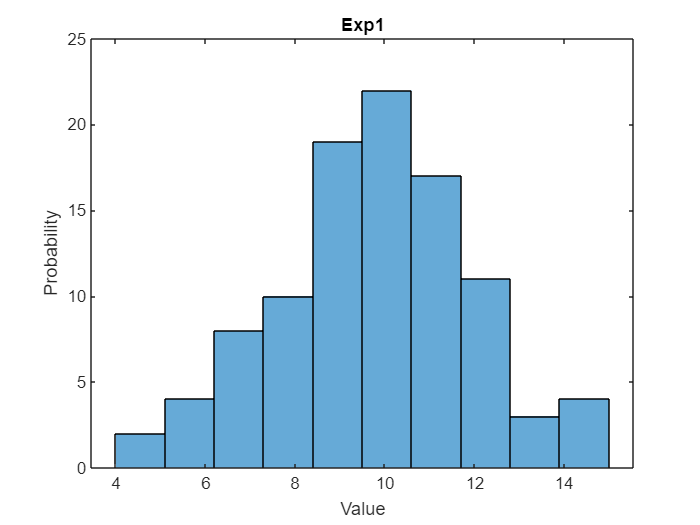

% Enter code for Question 1 here:

%SUPER TIP JAJAJJA, per a comentar tot un codig, selecionem totes les
%linies q volguem comentar i fem Ctl+R. Per descomentar fer Ctl+T

%Experiment 1
Exp1 = CreateNormalDistribution(10,2,100);
histogram(Exp1, 10);
title('Exp1');
xlabel('Value');
ylabel('Probability');

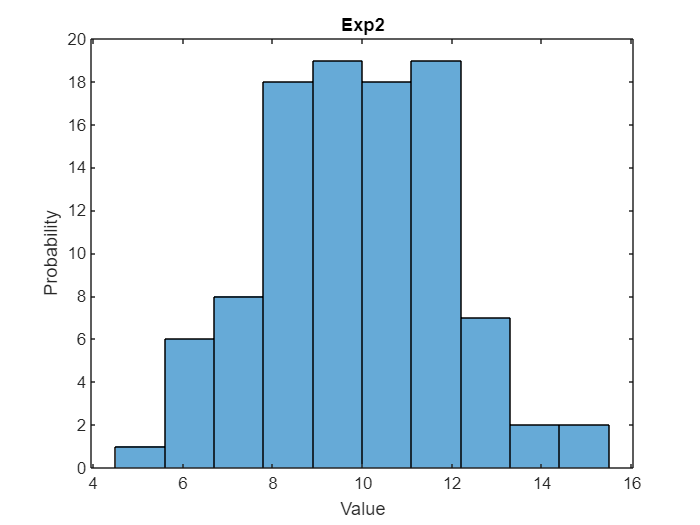


%Experiment 2
Exp2 = CreateNormalDistribution(10,2,100);
histogram(Exp2, 10);
title('Exp2');
xlabel('Value');
ylabel('Probability');

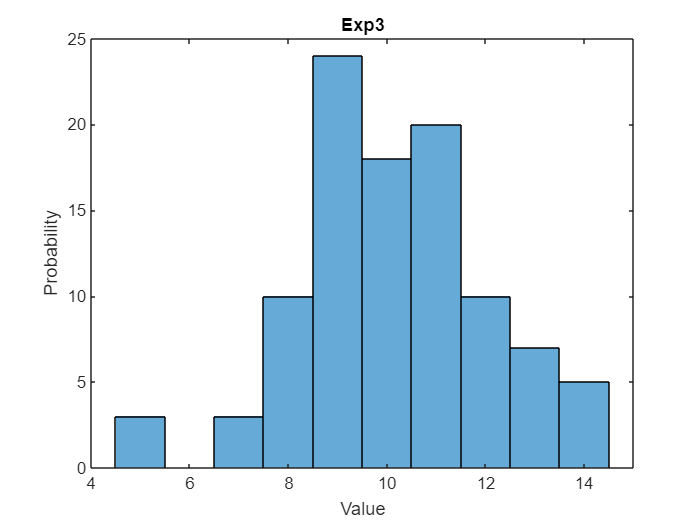


%Experiment 3
Exp3 = CreateNormalDistribution(10,2,100);
histogram(Exp3, 10);
title('Exp3');
xlabel('Value');
ylabel('Probability');

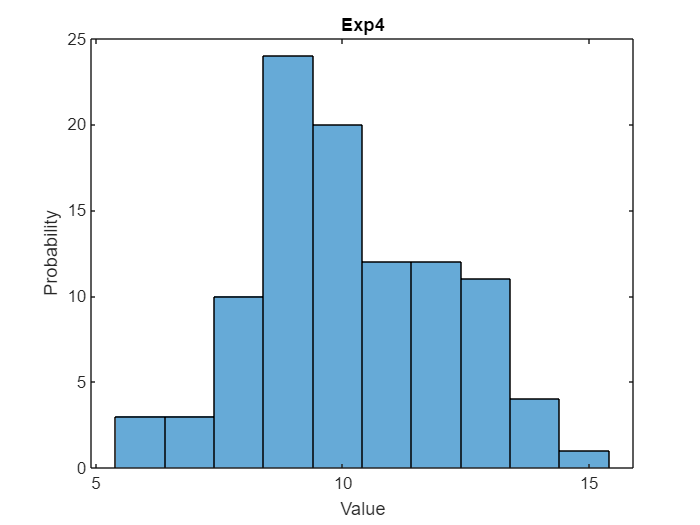


%Experiment 14
Exp4 = CreateNormalDistribution(10,2,100);
histogram(Exp4, 10);
title('Exp4');
xlabel('Value');
ylabel('Probability');

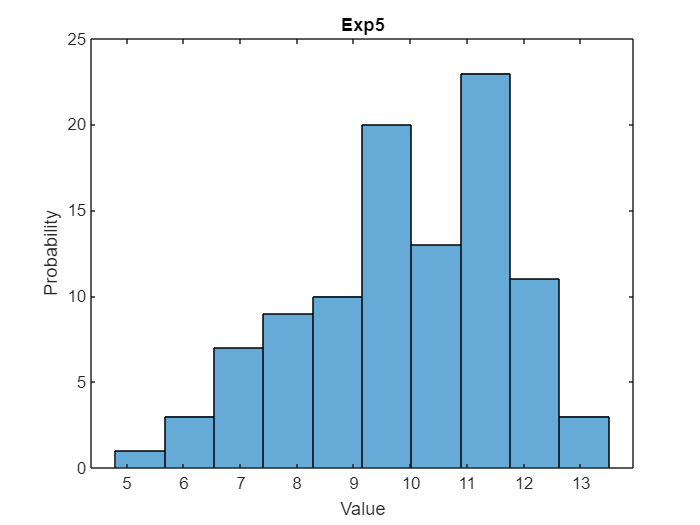


%Experiment 5
Exp5 = CreateNormalDistribution(10,2,100);
histogram(Exp5, 10);
title('Exp5');
xlabel('Value');
ylabel('Probability');



%We know that we could optimize the code by doing a for loop, but we would
%have problems by naming the different experiments and their plots (merge index to eperiments & histogram names)
%Hence, we can reuse these data for the incominng exercices.

%Regarding NumBins, we have been trying different values and believe that
%the best ones are between 8 and 12. Less or more than them, would lead to
%stange/incomplete histograms.



**Why do the histograms look different on each of the 5 experiments?**

Write your answer here.

Since we are working with normal distributions, each experiment has its own elements taken by random that differs from the other ones. However, they might share the same properties as similar shapes, but it is mathematically impossible to have 2 equal experiments using normal distribution. 

## Question 2

*(0.5 points)*

%Experiment 1
OurMean_Exp1 = CustomMade_Mean(Exp1)

OurMean_Exp1 = 9.8031

Mean_Exp1 = mean(Exp1);

%Experiment 2
OurMean_Exp2 = CustomMade_Mean(Exp2)

OurMean_Exp2 = 9.8632

Mean_Exp2 = mean(Exp2);

%Experiment 3
OurMean_Exp3 = CustomMade_Mean(Exp3)

OurMean_Exp3 = 10.1032

Mean_Exp3 = mean(Exp3);

%Experiment 4
OurMean_Exp4 = CustomMade_Mean(Exp4)

OurMean_Exp4 = 10.0970

Mean_Exp4 = mean(Exp4);

%Experiment 5
OurMean_Exp5 = CustomMade_Mean(Exp5)

OurMean_Exp5 = 9.9230

Mean_Exp5 = mean(Exp5);

%In all experiments, both OurMean and Mean computations have the same
%result. OurMean results are displayed on the bottom of the histograms.
%Despite having create each experimetn with a mean of 10, sice their
%elements are taken at random, the mean might change. However, our
%commputations are very close to 10, so they are correct.

**Why does the sample mean differ in each experiment?**

As said in the previous exercise, in each experiment the values were taken at random. That means that each one has different values, leading to similar but, different means.

## Question 3

*(0.5 points)*

%Experiment 1
OurStd_Exp1 = CustomMade_Std(Exp1)

OurStd_Exp1 = 2.1327

Std_Exp1 = std(Exp1);

%Experiment 2
OurStd_Exp2 = CustomMade_Std(Exp2)

OurStd_Exp2 = 2.0032

Std_Exp2 = std(Exp2);

%Experiment 3
OurStd_Exp3 = CustomMade_Std(Exp3)

OurStd_Exp3 = 1.9212

Std_Exp3 = std(Exp3);

%Experiment 4
OurStd_Exp4 = CustomMade_Std(Exp4)

OurStd_Exp4 = 1.9092

Std_Exp4 = std(Exp4);

%Experiment 5
OurStd_Exp5 = CustomMade_Std(Exp5)

OurStd_Exp5 = 1.8186

Std_Exp5 = std(Exp5);

%The std computation is based on the mean and values of each experiment.
%Since each of them have different values (hence different means), the
%variance will also be different in each experiment. However, observe
%that the std result are too closer. This is because of we are in a normal
%distribution. Values might change, but each experiment was done with a std
%of 2, so more or less our result is correct.

**Why does the sample standard deviation differ in each experiment?**

Write your answer and the 5 values obtained here.

## Question 4

*(1 point)*

% Enter code for Question 4 here:
Mle_Exp1 = CustomMle(Exp1)

Mle_Exp1 =     9.8031    2.1220


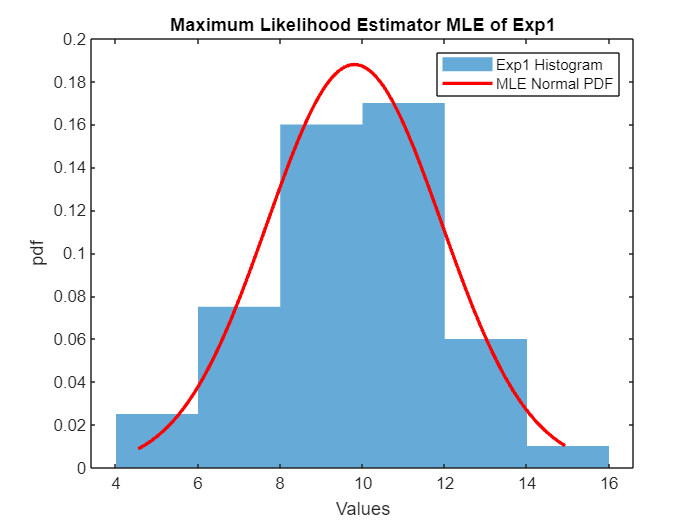


x = linspace(min(Exp1), max(Exp1), 100);
pdf_Mle = normpdf(x, Mle_Exp1(1), Mle_Exp1(2));


figure;
histogram(Exp1, 'Norm', 'pdf', 'EdgeColor', 'none');
hold on;
plot(x, pdf_Mle, 'r', 'LineWidth', 2);
legend('Exp1 Histogram', 'MLE Normal PDF');
xlabel('Values');
ylabel('pdf');
title('Maximum Likelihood Estimator MLE of Exp1');

## Question 5

*(2 points)*

% Enter code for Question 5 here:



## Question 6

*(1 point)*

#### $\alpha$:  lower margin - upper margin

`0.50: `

`0.10: `

`0.05: `

`0.01: `

Interpret here.

## Question 7

*(2 points)*

% Enter code for Question 7 here:



#### $\alpha$:  number

`0.50: /100`

`0.10: /100`

`0.05: /100`

`0.01: /100`

Interpret here.

## Question 8

*(2 points)*

% Enter code for Question 8 here:



Give the results of your tests here.

## Functions

% Place all functions here:

%Creation of the Normal Distribution experiments

function NormalDis = CreateNormalDistribution(mu, sigma, num_samples)
    NormalDis = normrnd(mu, sigma, 1, num_samples);
end


%Computing the sample mean
function OurMean = CustomMade_Mean(Distribution)
    OurMean = 0;
    for index=1:length(Distribution)
        OurMean = OurMean + Distribution(index);
    end
    OurMean = OurMean/length(Distribution);
end


%Commputing the sample standard deviation
function OurStd = CustomMade_Std(Distribution)
    OurMean = CustomMade_Mean(Distribution);
    OurStd = 0;
    for index=1:length(Distribution)
        OurStd = OurStd + ((Distribution(index) - OurMean)^2);
    end
    OurStd = OurStd / (length(Distribution) - 1);
    OurStd = sqrt(OurStd);
end

%Simulating the computation of the MLE
function OurMle = CustomMle(Distribution)
    OurMle(1) = CustomMade_Mean(Distribution);
    OurMle(2) = 0;                  %We can not use the CustoMade_Std function because it was the sample std
    for i=1:length(Distribution)    %We need the true std, not the sample one
        OurMle(2) = OurMle(2) + (Distribution(i) - OurMle(1))*(Distribution(i) - OurMle(1));
    end
    OurMle(2) = OurMle(2)/length(Distribution);
    OurMle(2) = sqrt(OurMle(2));    
end


